# Use Color Corrector

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads a network trained on the color correction data.

load ../data/ColorCast/colorcastnet.mat

## Task 1

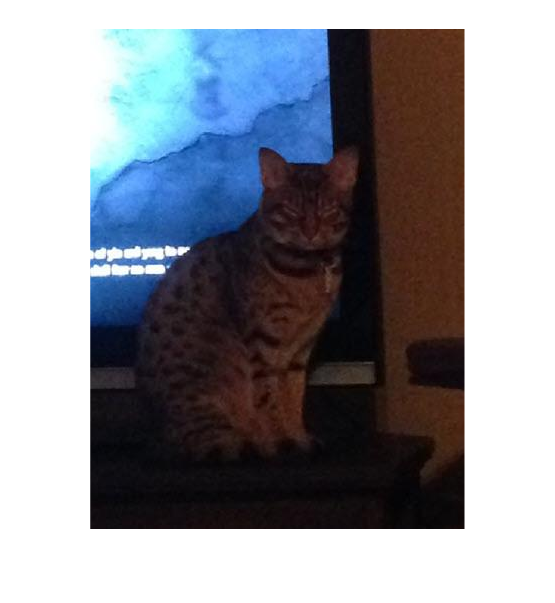

catim = imread("../data/cat_dark.jpg");
imshow(catim)

## Task 2

The displayed photo contains a cat, but it is hard to see because of the photo's lighting. Before you can use this image with the network, it must be resized to match GoogLeNet's image input layer. Recall that GoogLeNet expects images sized `[224 224]`.

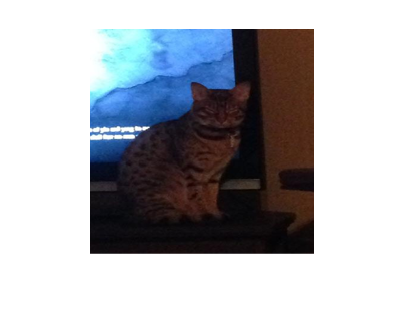

testim = imresize(catim, [224 224]);
imshow(testim)

## Task 3

The `predict` function accepts two inputs, the network and an image.

`response` `=` `predict``(``net``,``im``)`

predrgb = predict(ccnet, testim)

predrgb = 1×3 single row vector
  -42.5282  -39.2599  -10.9195


## Task 4

The function `correctColor` has been already created and can be viewed at the bottom of the script. It accepts two inputs, the image to fix and the RGB vector to use.

`fixed` `=` `correctColor``(``im``,``rgb``)`

fixedim = correctColor(catim, predrgb);

## Task 5

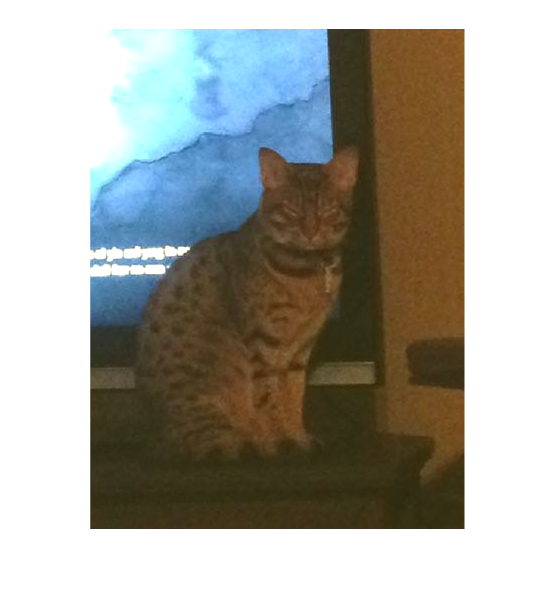

imshow(fixedim)

This function modifies an input image using a vector of 3 RGB values.

function fixedim = correctColor(im, rgb)
    fixedim = uint8(single(im) - reshape(rgb, [1 1 3]));
end